Let's start by fixing the path

clear
clc

full_path='/storage/work/mjv5465/SAFE/';

restoredefaultpath;
addpath(genpath([full_path,'Data/']));
addpath(genpath([full_path,'Functions']));
addpath(genpath([full_path,'Scratch/']));
cd([full_path,'Scratch/']);

clear full_path  

## Let's start with value

We'll compare the Fama-French value definition with the one from Asness and Frazzini (2013).

clear
clc

load NYSE
load ret
load me
load dates
load ff
load BE
load R


Fama and French (1993) use December market equity in the denominator of book-to-market. The idea is to align the timing for market equity with the fiscal-year-end for most firms.

bmFF = BE./lag(me,6,nan);  

Asness and Frazzini (2013), on the other hand, argue that this is suboptimal:

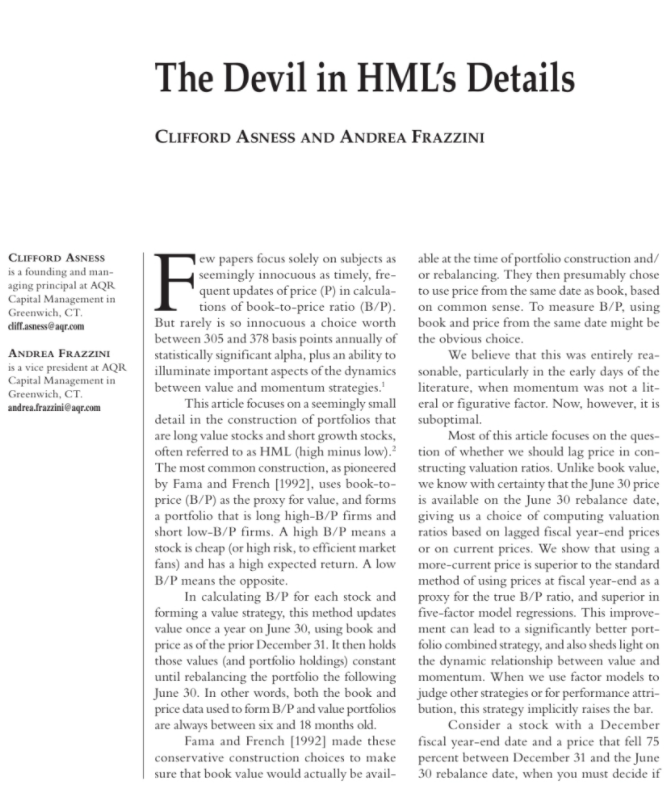

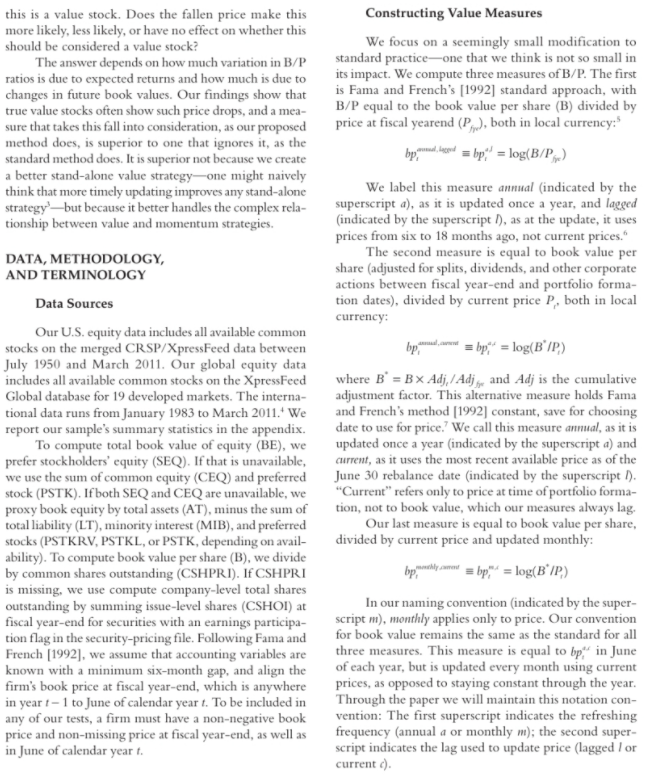

What they advocate is to use the most recent market equity observation. They have both annual and monthly-updated one, but here we'll focus on the latter:

bmAF = FillMonths(BE)./me; 

Let's compare the two now:

indBMFF = makeUnivSortInd(bmFF, 5, NYSE);
resFF = runUnivSort(ret, indBMFF, dates, me, 'weighting', 'v', ...
                                             'timePeriod', 196306, ...
                                             'plotFigure', 0);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
              1    0.565    0.111     1.017   -0.080    -0.360   -0.007
                 [ 3.09]  [ 3.24]  [127.50]  [-6.97]  [-30.83]  [-0.87]
                                                                       
              2    0.571    0.003    0.987   -0.046    0.056   -0.001  
                 [ 3.40]  [ 0.06]  [92.38]  [-3.04]  [ 3.56]  [-0.05]  
                                                                       
              3    0.616   -0.013    0.969   -0.020    0.274    0.004  
                 [ 3


indBMAF = makeUnivSortInd(bmAF, 5, NYSE);
resAF = runUnivSort(ret, indBMAF, dates, me, 'weighting', 'v', ...
                                             'timePeriod', 196306, ...
                                             'plotFigure', 0);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
              1    0.556    0.028     1.029   -0.066    -0.341    0.090
                 [ 3.04]  [ 0.83]  [130.64]  [-5.86]  [-29.57]  [11.18]
                                                                       
              2    0.529   -0.044    0.993   -0.096    0.095   -0.002  
                 [ 3.16]  [-0.92]  [89.57]  [-6.04]  [ 5.86]  [-0.22]  
                                                                       
              3    0.616    0.019    0.973   -0.053    0.325   -0.069  
                 [ 3

Now let's see how they do when combined with momentum:

% Create the cross-sectional rank variables
bmFF_rank = tiedrank(FillMonths(bmFF)')';
bmAF_rank = tiedrank(bmAF')';
R_rank = tiedrank(R')';


% Combine them
bmFFR = bmFF_rank + R_rank;
bmAFR = bmAF_rank + R_rank;

indBMFFR = makeUnivSortInd(bmFFR, 5, NYSE);
resFFR = runUnivSort(ret, indBMFFR, dates, me, 'weighting', 'v', ...
                                               'timePeriod', 196306, ...
                                               'plotFigure', 0);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
              1    0.308    0.062    1.003   -0.001    -0.213    -0.436
                 [ 1.53]  [ 1.27]  [88.35]  [-0.09]  [-12.87]  [-37.39]
                                                                       
              2    0.569    0.120    0.961   -0.105   -0.068   -0.098  
                 [ 3.37]  [ 2.49]  [85.31]  [-6.51]  [-4.16]  [-8.45]  
                                                                       
              3    0.699    0.035    0.993    0.020    0.051    0.136  
                 [ 4


indBMAFR = makeUnivSortInd(bmAFR, 5, NYSE);
resAFR = runUnivSort(ret, indBMAFR, dates, me, 'weighting', 'v', ...
                                               'timePeriod', 196306, ...
                                               'plotFigure', 0);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
              1    0.281   -0.005    0.989   -0.027    -0.217    -0.347
                 [ 1.46]  [-0.10]  [86.30]  [-1.63]  [-12.94]  [-29.46]
                                                                       
              2    0.597    0.137    0.961   -0.095   -0.044   -0.094  
                 [ 3.55]  [ 2.86]  [85.76]  [-5.93]  [-2.69]  [-8.20]  
                                                                       
              3    0.663   -0.015    1.005    0.033    0.022    0.157  
                 [ 3

## Let's look at investment next

There are quite a few papers that propose investment-related sorting variables. We'll replicate a few of them here and compare how the investment variables do relative to each other. Let's load a bunch of stuff first:

clear
clc

load ret
load me
load dates
load NYSE
load AT
load CAPX
load PPEGT
load INVT
load shrout
load cfacshr
load FinFirms
load DLTT
load DLC
load NI
load DVP
load DVC
load BE

CAPX(FinFirms==1) = nan;
AT(FinFirms==1) = nan;

The first replication will be the CAPX growth variable from Anderson and Garcia-Feijoo (JF, 2006):

cegth2 = CAPX./lag(CAPX,24,nan)-1;
ind = makeUnivSortInd(-cegth2, 5);
res = runUnivSort(ret, ind, dates, me, 'timePeriod', [197606 199906]); 

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                     
              1    0.546   -0.143    1.087    0.340   -0.350   -0.087
                 [ 1.60]  [-1.51]  [46.61]  [ 9.86]  [-8.61]  [-3.07]
                                                                     
              2    0.723    0.030    1.017   -0.046   -0.175   -0.036
                 [ 2.53]  [ 0.44]  [60.97]  [-1.87]  [-6.03]  [-1.80]
                                                                     
              3    0.806    0.075    0.917   -0.142    0.028    0.029
                 [ 3.35]  [ 1.57]  [

Compare this with Table III, Panel C from the paper:

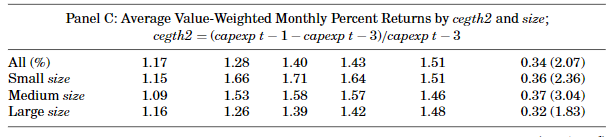

And let's also run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-cegth2, 10, NYSE);
resCG = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up is the asset growth effect from Cooper, Gullen, and Schill (JF, 2008):

assetGrowth = AT./lag(AT,12,nan);
ind = makeUnivSortInd(assetGrowth, 10);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'e', ...
                                       'timePeriod', [196806 200306]); 

     ---------------------------------------------------------------------------- 
              Equally-weighted  portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
               1    1.294    0.840    0.997    1.596    0.190   -0.253 
                  [ 2.89]  [ 3.51]  [18.40]  [22.36]  [ 2.23]  [-4.67] 
                                                                       
               2    1.168    0.706    0.909    1.249    0.228   -0.179 
                  [ 3.30]  [ 4.52]  [25.69]  [26.81]  [ 4.10]  [-5.08] 
                                                                       
               3    0.997    0.508    0.919    0.864    0.370   -0.179 
                 

Their t-stats are outrageous, but we are not too far off:

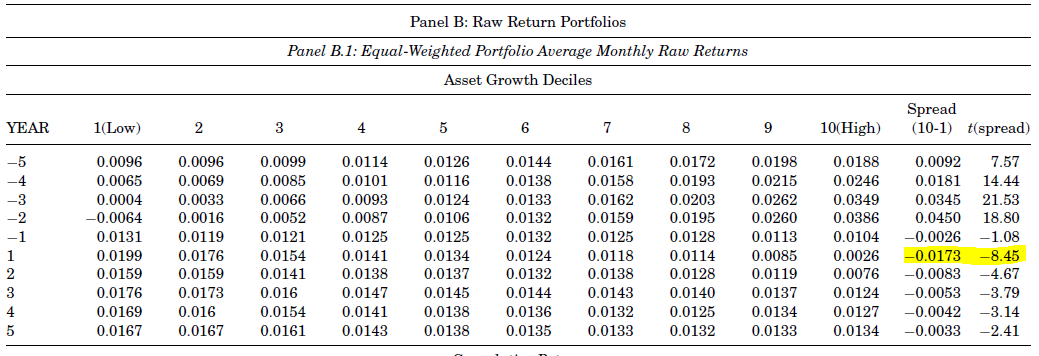

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-assetGrowth, 10, NYSE);
resAG = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, net issuance from Pontiff and Woodgate (JF, 2008). Although technically not an investment variable, it is quite closely linked with the investment effect.

ashrout = shrout.*cfacshr;
dashrout = log(ashrout ./ lag(ashrout,12,nan)); % percent change in split adjusted shares outstanding
dashrout(dates - 10*floor(dates/10) ~= 6,:) = nan;

runFamaMacBeth(100*ret,dashrout, dates, 'timePeriod', [197001 200312]); 

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.419        4.954 
                    var 1       -2.356       -6.642 

---------------------------------------------------------------------- 


Compare this with the paper result:

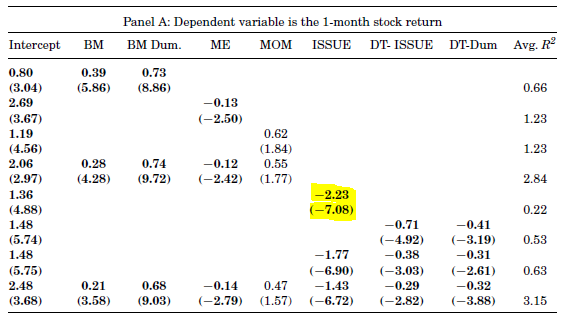

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(-dashrout, 10, NYSE);
resNI = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, investment variable from Lyandres, Sun, and Zhang (RFS, 2008). They don't really report a proper sort on this. They instead construct an investor factor that is similar in spirit to the Fama-French factors, but has a more involved construction. We'll just run the value-weighted decile NYSE break sort:

investment = ( PPEGT - lag(PPEGT, 12, nan) + ...
               INVT  - lag(INVT, 12, nan)  ) ...
               ./lag(AT,12,nan);

ind = makeUnivSortInd(-investment, 10, NYSE);
resInv = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Now let's compare the strategy returns:

retCG = resCG.pret(:,end);
retAG = resAG.pret(:,end);
retNI = resNI.pret(:,end);
retInv = resInv.pret(:,end);
dates = resInv.dates;
const = 0.01*ones(size(dates));

y = [retCG retAG retNI retInv];

corrcoef(y(2:end,:))

ans =     1.0000    0.4912    0.1596    0.4572
    0.4912    1.0000    0.3160    0.6183
    0.1596    0.3160    1.0000    0.2769
    0.4572    0.6183    0.2769    1.0000


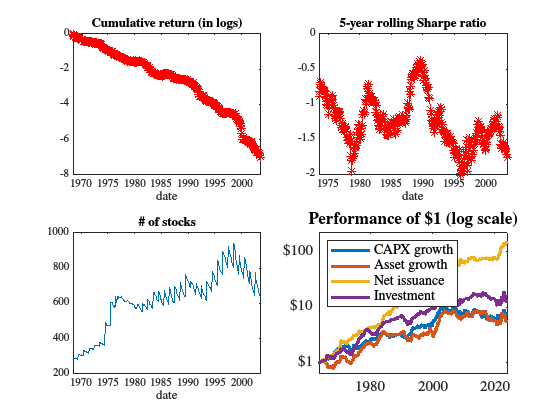


ibbots(y, dates, 'legendLabels', {'CAPX growth','Asset growth','Net issuance','Investment'}, ...
                 'linPlotInd', 0);


prt(nanols(retCG,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0011 
Durbin-Watson  =    1.8756 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.332425         2.740124         0.006293 



prt(nanols(retAG,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0014 
Durbin-Watson  =    1.8084 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.296272         2.149122         0.031955 



prt(nanols(retNI,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0009 
Durbin-Watson  =    1.7179 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.726037         6.419561         0.000000 



prt(nanols(retInv, [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0012 
Durbin-Watson  =    1.7673 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.405825         3.095981         0.002037 



And run some spanning tests:

prt(nanols(retCG,  [const retAG retNI retInv]))

Ordinary Least-squares Estimates 
R-squared      =    0.2797 
Rbar-squared   =    0.2767 
sigma^2        =    0.0008 
Durbin-Watson  =    1.9195 
Nobs, Nvars    =    726,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.163018         1.534308         0.125392 
variable 2         0.300744         8.345503         0.000000 
variable 3        -0.019128        -0.532424         0.594596 
variable 4         0.232101         6.202386         0.000000 



prt(nanols(retAG,  [const retCG retNI retInv]))

Ordinary Least-squares Estimates 
R-squared      =    0.4574 
Rbar-squared   =    0.4551 
sigma^2        =    0.0008 
Durbin-Watson  =    1.9331 
Nobs, Nvars    =    726,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1        -0.127803        -1.218893         0.223283 
variable 2         0.292534         8.345503         0.000000 
variable 3         0.179873         5.168419         0.000000 
variable 4         0.483545        14.508052         0.000000 



prt(nanols(retNI,  [const retCG retAG retInv]))

Ordinary Least-squares Estimates 
R-squared      =    0.1109 
Rbar-squared   =    0.1073 
sigma^2        =    0.0008 
Durbin-Watson  =    1.7786 
Nobs, Nvars    =    726,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.625955         5.810483         0.000000 
variable 2        -0.020518        -0.532424         0.594596 
variable 3         0.198351         5.168419         0.000000 
variable 4         0.118614         3.000641         0.002787 



prt(nanols(retInv, [const retCG retAG retNI]))

Ordinary Least-squares Estimates 
R-squared      =    0.4206 
Rbar-squared   =    0.4182 
sigma^2        =    0.0007 
Durbin-Watson  =    1.9245 
Nobs, Nvars    =    726,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.119677         1.161567         0.245795 
variable 2         0.217951         6.202386         0.000000 
variable 3         0.466810        14.508052         0.000000 
variable 4         0.103842         3.000641         0.002787 



Finally, let's run some Fama-MacBeths:

runFamaMacBeth(100*ret, [cegth2],                                 dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.456        5.460 
                    var 1       -0.061       -4.084 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [assetGrowth],                            dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        2.334        8.427 
                    var 1       -0.867       -4.652 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [dashrout],                               dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.438        4.764 
                    var 1       -1.311       -3.086 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [investment],                             dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.546        5.836 
                    var 1       -1.534       -7.331 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [cegth2 assetGrowth dashrout investment], dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.332        3.658 
                    var 1       -0.015       -0.987 
                    var 2        0.252        0.877 
                    var 3       -1.862       -5.144 
                    var 4       -1.393       -4.437 

---------------------------------------------------------------------- 


## Profitability is next

Similar story to investment. Quite a few papers out there. We'll look at 4 different profitability proxies:

clear
clc

load ret
load me
load dates
load NYSE
load AT
load FinFirms
load GP 
load bm
load REVT
load COGS
load XSGA
load XINT
load XRD
load BE
load DRC
load DRLT
load RECT
load RECT
load XPP
load AP
load INVT
load XACC
load BEQ
load IBQ

AT(FinFirms==1) = nan;
BE(FinFirms==1) = nan;
BEQ(FinFirms==1) = nan;

Let's start with Novy-Marx (2012) - gross profitability:

GrossProf = GP./AT;
ind = makeUnivSortInd(GrossProf, 5, NYSE);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                       'timePeriod', [196306 201012], ...
                                       'factorModel', 3); 

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 3-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml
                                                             
              1    0.289   -0.216    0.956    0.031    0.181 
                 [ 1.52]  [-3.04]  [57.88]  [ 1.34]  [ 7.12] 
                                                             
              2    0.375   -0.116    1.005   -0.072    0.153 
                 [ 1.91]  [-1.68]  [62.82]  [-3.19]  [ 6.22] 
                                                             
              3    0.518    0.037    1.004    0.054    0.050 
                 [ 2.59]  [ 0.61]  [72.18]  [ 2.76]  [ 2.35] 
                                               

Compare with the result in the paper:

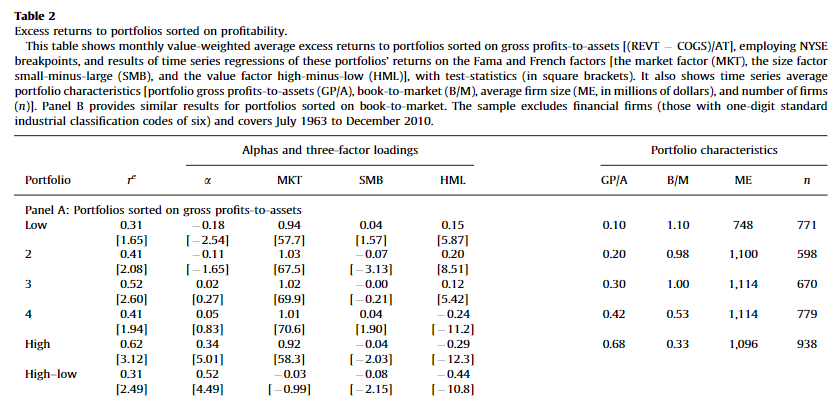

The results that sold the paper and made Robert really famous in the factor investing industry was the significantly negative loading on HML. Value and gross profitability work really well together. This led to an explosion of "quality" funds and his work was heavily used in marketing those. To see why that's important, look at the performance of value, gross profitability, and a combo of the two:

% Create the cross-sectional rank variables
gp_rank = tiedrank(GrossProf')';
bm_rank = tiedrank(bm')';

% Combine them
gp_bm = gp_rank + bm_rank;

% Sort on gross profitability
ind = makeUnivSortInd(GrossProf, 10, NYSE);
resGP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

% Sort on book-to-market
ind = makeUnivSortInd(bm, 10, NYSE);
resBM = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

% Sort on the combined rank
ind = makeUnivSortInd(gp_bm, 10, NYSE);
resGPBM = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 


retGP = resGP.pret(:, end);
retBM = resBM.pret(:, end);
retGPBM = resGPBM.pret(:, end);

ibbots([retGP retBM retGPBM], resGP.dates, 'legendLabels', {'GP','BM','GP+BM'});

Let's look at Fama and French's (2015) operating profitability:

OP = REVT + nanmatsum(-COGS, -nanmatsum(XSGA, XINT));
OpProf = OP./BE;

ind = makeBivSortInd(me, 5, OpProf, 5, 'sortType', 'unconditional', ...
                                       'breaksFilterInd', NYSE);
[res, ~] = runBivSort(ret, ind, 5, 5, dates, me, 'timePeriod', [196306 201312]);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 4-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      umd
                                                                       
               1    0.586   -0.261    1.031    1.440    0.057   -0.044 
                  [ 1.88]  [-2.54]  [43.12]  [42.87]  [ 1.53]  [-1.84] 
                                                                       
               2    0.967    0.138    0.945    1.062    0.303   -0.013 
                  [ 3.90]  [ 2.09]  [61.46]  [49.16]  [12.60]  [-0.84] 
                                                                       
               3    0.940    0.113    0.948    1.014    0.344   -0.024 
                  [ 

Compare with:

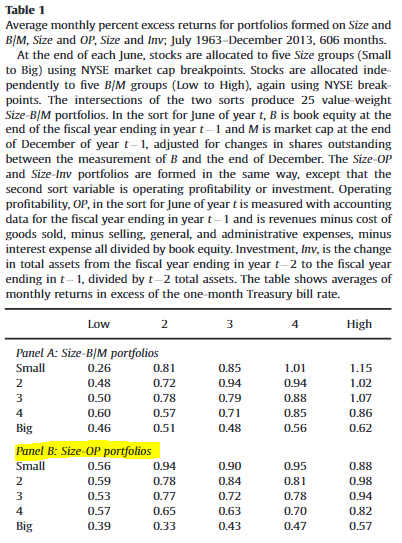

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(OpProf, 10, NYSE);
resOP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Next up, Ball, Gerakos, Linnainmaa, and Nikolaev's (JFE, 2016) cash-based profitability:

% They start out with a slightly different operating profitability measure:
OP = REVT - nanmatsum(COGS, nanmatsum(XSGA, -XRD));

% Deferred revenue
DR = DRC + DRLT;

% Exlude zero or negative book value
BE(BE <= 0) = nan;

% Create changes in variables that enter accruals calculation
dRECT = RECT-lag(RECT,12,nan); % Receivables
dXPP  = XPP-lag(XPP,12,nan);   % Prepaid expenses
dAP   = AP-lag(AP,12,nan);     % Account payable
dINVT = INVT-lag(INVT,12,nan); % Inventories
dDR   = DR-lag(DR,12,nan);     % Deferred revenue
dXACC = XACC-lag(XACC,12,nan); % Accued expenses

% Create accruals
Accruals = nanmatsum(zeros(size(dRECT)), ... 
                     nanmatsum(dRECT,  ...
                     nanmatsum(dINVT, ...
                     nanmatsum(dXPP, ...
                     nanmatsum(-dAP, ...
                     nanmatsum(-dDR, -dXACC))))));

% Create cash-profitability
CP = OP - Accruals;

% Scale it by total assets
CashProf = CP ./ AT;

ind = makeUnivSortInd(CashProf, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306 201412], ...
                                         'factorModel', 1, ...
                                         'printResults', 1 ,...
                                         'plotFigure', 0); 

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              CAPM
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt
                                            
               1    0.156   -0.504    1.300 
                  [ 0.61]  [-5.04]  [58.25] 
                                            
               2    0.440   -0.117    1.098 
                  [ 2.08]  [-1.52]  [63.75] 
                                            
               3    0.454   -0.038    0.970 
                  [ 2.43]  [-0.55]  [62.25] 
                                            
               4    0.439   -0.060    0.984 
                  [ 2.33]  [-0.91]  [66.20] 
                                            
               5    0.561    0.079    0.949 
                  [

Compare with:

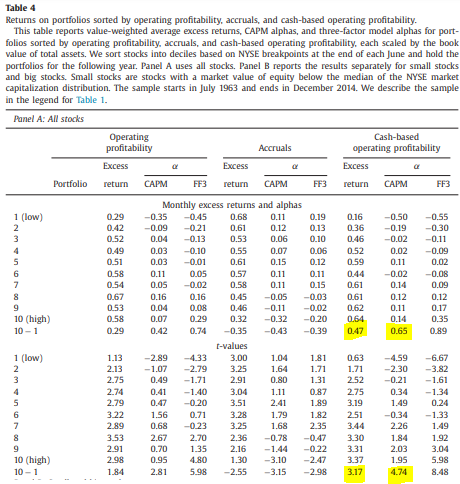

Let's again run this with a value-weighted decile NYSE break sort for the spanning tests later:

ind = makeUnivSortInd(CashProf, 10, NYSE);
resCP = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 


Finally, Lu Zhang and co-authors (e.g., Hou, Xue, and Zhang, 2015) use an ROE-based profitability factor. It uses quarterly data. Let's  run this with a value-weighted decile NYSE break sort for the spanning tests later:

roe = IBQ./lag(BEQ,3,nan);
ind = makeUnivSortInd(roe, 10, NYSE);
resROE = runUnivSort(ret, ind, dates, me, 'weighting', 'v', ...
                                         'timePeriod', [196306], ...
                                         'printResults', 0 ,...
                                         'plotFigure', 0); 

Now let's compare the strategy returns:

retGP = resGP.pret(:,end);
retOP = resOP.pret(:,end);
retCP = resCP.pret(:,end);
retROE = resROE.pret(:,end);
dates = resROE.dates;
const = 0.01*ones(size(dates));

y = [retGP retOP retCP retROE];

corrcoef(y(2:end,:))

ans =     1.0000    0.3871    0.4514       NaN
    0.3871    1.0000    0.6102       NaN
    0.4514    0.6102    1.0000       NaN
       NaN       NaN       NaN       NaN


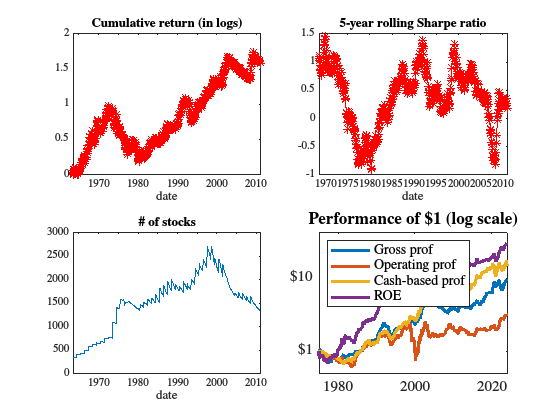


ibbots(y, dates, 'timePeriod', 197501, 'legendLabels', {'Gross prof','Operating prof','Cash-based prof','ROE'});


prt(nanols(retGP,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0011 
Durbin-Watson  =    1.8207 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.440902         3.541698         0.000423 



prt(nanols(retOP,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0017 
Durbin-Watson  =    1.6585 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.202891         1.318121         0.187880 



prt(nanols(retCP,  [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0014 
Durbin-Watson  =    1.7602 
Nobs, Nvars    =    726,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.510857         3.622215         0.000312 



prt(nanols(retROE, [const]))

Ordinary Least-squares Estimates 
R-squared      =    0.0000 
Rbar-squared   =    0.0000 
sigma^2        =    0.0022 
Durbin-Watson  =    1.6647 
Nobs, Nvars    =    624,     1 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.751705         3.966857         0.000081 



And run some spanning tests:

prt(nanols(retGP,  [const retOP retCP retROE]))

Ordinary Least-squares Estimates 
R-squared      =    0.2879 
Rbar-squared   =    0.2845 
sigma^2        =    0.0008 
Durbin-Watson  =    1.8118 
Nobs, Nvars    =    624,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.105839         0.897086         0.370021 
variable 2         0.031404         0.716995         0.473647 
variable 3         0.362768         9.550361         0.000000 
variable 4         0.107771         2.889013         0.004000 



prt(nanols(retOP,  [const retGP retCP retROE]))

Ordinary Least-squares Estimates 
R-squared      =    0.6132 
Rbar-squared   =    0.6114 
sigma^2        =    0.0007 
Durbin-Watson  =    1.8885 
Nobs, Nvars    =    624,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1        -0.321309        -2.990779         0.002893 
variable 2         0.026381         0.716995         0.473647 
variable 3         0.294354         8.323478         0.000000 
variable 4         0.531351        19.674772         0.000000 



prt(nanols(retCP,  [const retGP retOP retROE]))

Ordinary Least-squares Estimates 
R-squared      =    0.4602 
Rbar-squared   =    0.4576 
sigma^2        =    0.0008 
Durbin-Watson  =    1.8662 
Nobs, Nvars    =    624,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.253291         2.181692         0.029507 
variable 2         0.353519         9.550361         0.000000 
variable 3         0.341463         8.323478         0.000000 
variable 4         0.111759         3.036978         0.002490 



prt(nanols(retROE, [const retGP retOP retCP]))

Ordinary Least-squares Estimates 
R-squared      =    0.5778 
Rbar-squared   =    0.5758 
sigma^2        =    0.0010 
Durbin-Watson  =    1.8768 
Nobs, Nvars    =    624,     4 
***************************************************************
Variable        Coefficient      t-statistic    t-probability 
variable 1         0.443515         3.548396         0.000417 
variable 2         0.123253         2.889013         0.004000 
variable 3         0.723381        19.674772         0.000000 
variable 4         0.131158         3.036978         0.002490 



Finally, let's run some Fama-MacBeths:

runFamaMacBeth(100*ret, [GrossProf],                     dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.167        4.418 
                    var 1        0.494        3.369 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [OpProf],                        dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.381        5.085 
                    var 1       -0.050       -0.342 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [CashProf],                      dates, 'timePeriod', 196306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.234        4.401 
                    var 1        0.964        3.036 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [roe],                           dates, 'timePeriod', 197306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.241        2.453 
                    var 1        7.310        2.816 

---------------------------------------------------------------------- 


runFamaMacBeth(100*ret, [GrossProf OpProf CashProf roe], dates, 'timePeriod', 197306);

---------------------------------------------------------------------- 
           Results from Fama - MacBeth regressions 
---------------------------------------------------------------------- 
                                 Coeff       t-stat 
                    var 0        1.265        2.484 
                    var 1        0.128        0.472 
                    var 2       -0.791       -3.344 
                    var 3        0.760        1.579 
                    var 4        8.190        3.536 

---------------------------------------------------------------------- 
